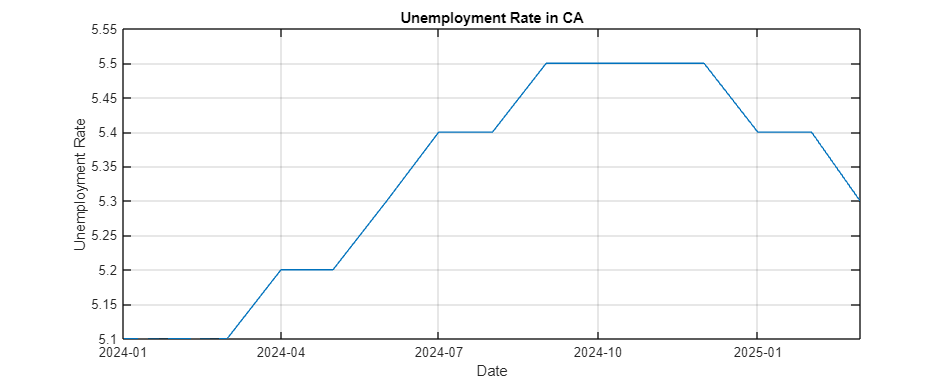

clear all;
close all;
clc;
% Section 5: result of March unemployment.
% Comparing the realized UR to our predicted UR
data = readtable("CAUR(March).csv");

date = datetime(data.observation_date, 'InputFormat', 'yyyy-MM-dd'); 
urate = data.CAUR;

% Plot
figure('Position', [100, 100, 1000, 400]); 
plot(date, urate, 'LineWidth', 1); 
title('Unemployment Rate in CA');
xlabel('Date');
ylabel('Unemployment Rate');
grid on;
xtickformat('yyyy-MM');
xlim([datetime(2024,1,1), datetime(2025,3,1)]);

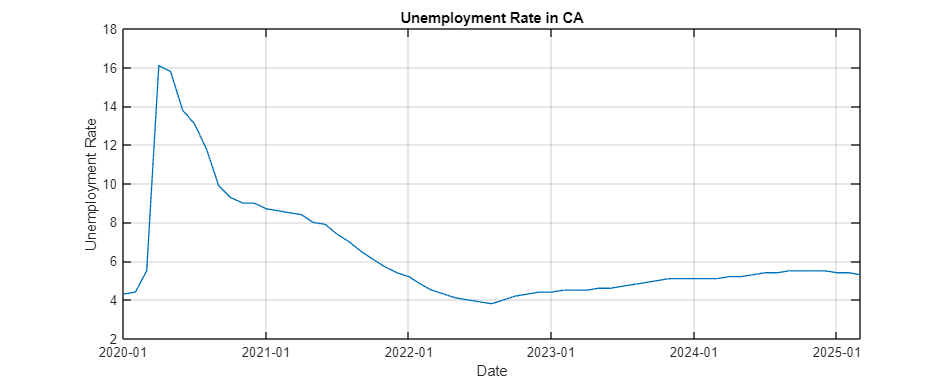

% Plot
figure('Position', [100, 100, 1000, 400]);  
plot(date, urate, 'LineWidth', 1); 
title('Unemployment Rate in CA');
xlabel('Date');
ylabel('Unemployment Rate');
grid on;
xtickformat('yyyy-MM');
xlim([datetime(2020,1,1), datetime(2025,3,1)]);

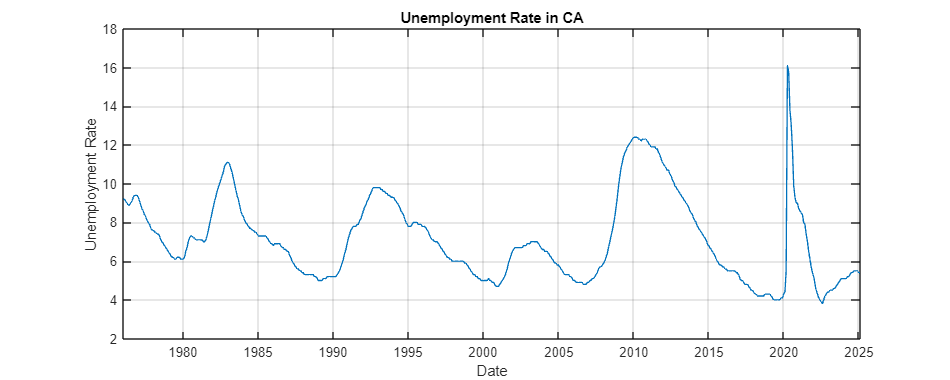

% Section 2:AR forecast part
data = readtable("CAUR.csv");

date = datetime(data.observation_date, 'InputFormat', 'yyyy-MM-dd');  
urate = data.CAUR;

figure('Position', [100, 100, 1000, 400]);  
plot(date, urate, 'LineWidth', 1); 
title('Unemployment Rate in CA');
xlabel('Date');
ylabel('Unemployment Rate');
grid on;
xtickformat('yyyy');
xlim([datetime(1976,1,1), datetime(2025,2,1)]);

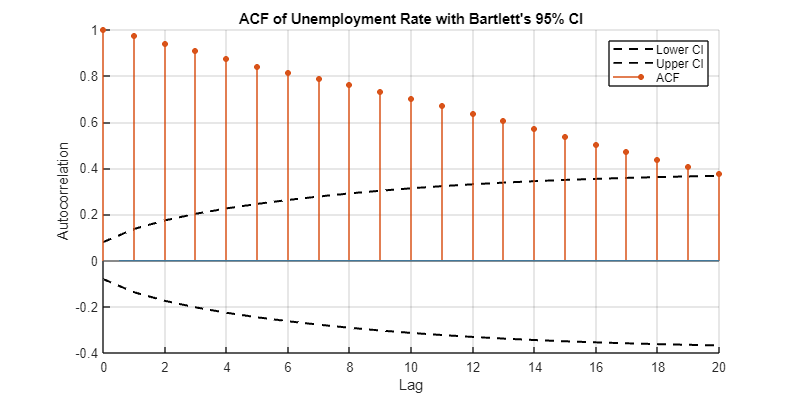

%% Use ACF and PACF to give an idea about lags
data = readtable("CAUR.csv");
y = data.CAUR;
date = datetime(data.observation_date);

% % ACF
% figure;
% autocorr(y, 'NumLags', 20);
% title('ACF of Unemployment Rate');

y = data.CAUR;
T = length(y);

q = 20;  % number of lags we consider

% ACF
acf = autocorr(y, 'NumLags', q);  % ACF from lag 0 to q

% Bartlett confidence interval
% whh(k) = 1 + 2 * sum(acf(2:k+1).^2)
whh = 2 * cumsum(acf.^2) - 1;

ci_bart = zeros(q+1, 2);  % lag 0 to q
ci_bart(:,2) =  1.96 * sqrt(whh / T);   % Upper bound
ci_bart(:,1) = -1.96 * sqrt(whh / T);   % Lower bound

% Plot
figure('Position', [100, 100, 800, 400]);
hold on;

% Bartlett CI
plot(0:q, ci_bart(:,1), 'k--', 'LineWidth', 1.5);
plot(0:q, ci_bart(:,2), 'k--', 'LineWidth', 1.5);

% plotting ACF
autocorr(y, 'NumLags', q, 'NumSTD', 0); 
title('ACF of Unemployment Rate with Bartlett''s 95% CI');
xlabel('Lag');
ylabel('Autocorrelation');
legend('Lower CI', 'Upper CI', 'ACF');
grid on;

2. 

% ADF unit root test
clear all
data = readtable("CAUR.csv");

y = data.CAUR;

% Step 3: ADF test: with intercept, without trend, and have 12 lags
[h, pValue, stat, cValue, reg] = adftest(y, Model="ARD", lags=11);

fprintf("\n--- ADF Test: Model = ARD, lags = 12 ---\n");


--- ADF Test: Model = ARD, lags = 12 ---


fprintf("rejecting unit root or not: %d \n", h);

rejecting unit root or not: 1 


fprintf("ADF result: %.4f\n", stat);

ADF result: -3.2964


fprintf("p-value: %.4f\n", pValue);

p-value: 0.0156


disp(cValue);

   -2.8675



3. Choose lags

% AIC
data = readtable("CAUR.csv"); 
y = data.CAUR;
T = length(y);

maxP = 12;
aic_values = nan(maxP,1);

% t = 13
start_idx = maxP + 1;

for p = 1:maxP
    Y = y(start_idx:end);
    
    X = ones(length(Y), 1); 
    for i = 1:p
        X = [X, y(start_idx - i:end - i)];
    end
    
    
    mdl = fitlm(X, Y);
    aic_values(p) = mdl.ModelCriterion.AIC;
end


% AIC table 
aic_table = table((1:maxP)', aic_values, 'VariableNames', {'Lag', 'AIC'});
disp('AIC for AR(p) with fixed t = 13 start:');

AIC for AR(p) with fixed t = 13 start:


disp(aic_table);

    Lag     AIC  
    ___    ______

     1     796.52
     2     776.53
     3     776.33
     4     774.43
     5     775.16
     6     774.94
     7     776.66
     8     778.35
     9     778.28
    10     780.23
    11     781.27
    12      782.8




% best AIC 
[minAIC, best_p] = min(aic_values);
fprintf('\n best p = %d，with AIC = %.2f\n', best_p, minAIC);


 best p = 4，with AIC = 774.43


2.3

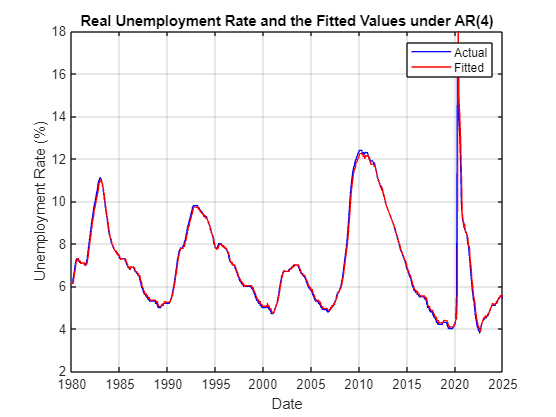

% AR(4)
clear all
data = readtable("CAUR.csv");
urate = data.CAUR;
date_obj = datetime(data.observation_date);

% setting lags
lags = 4;
n = length(urate) - lags;
y = urate(lags+1:end);

% X（cons + lags）
X = ones(n, 1);
for i = 1:lags
    X(:,i+1) = urate(lags+1-i:end-i);  
end

% OLS 
[beta, ~, residuals] = regress(y, X);
fitted = X * beta;

figure;
plot(date_obj, urate, 'b-', 'LineWidth', 1); hold on;
plot(date_obj(lags+1:end), fitted, 'r-', 'LineWidth', 1);
title('Real Unemployment Rate and the Fitted Values under AR(4)');
legend('Actual', 'Fitted');
xlabel('Date'); ylabel('Unemployment Rate (%)');
grid on; datetick('x', 'yyyy', 'keepticks');

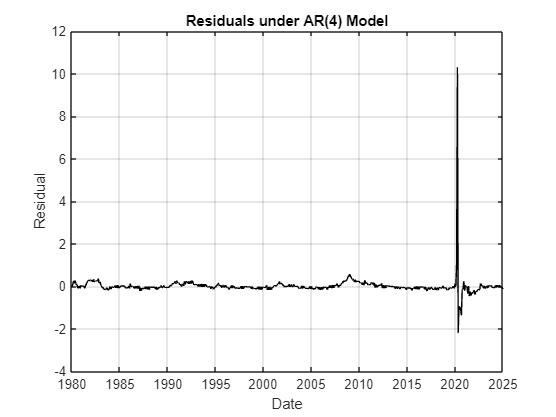


figure;
%subplot(2,1,1);
plot(date_obj(lags+1:end), residuals, 'k');
title('Residuals under AR(4) Model');
xlabel('Date'); ylabel('Residual');
grid on; datetick('x', 'yyyy', 'keepticks');

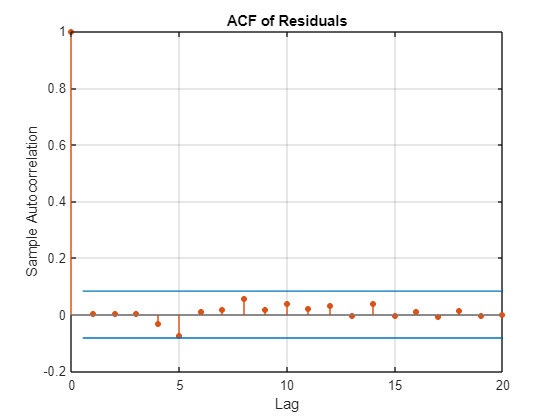


%subplot(2,1,2);
figure;
autocorr(residuals, 'NumLags', 20);
title('ACF of Residuals');

T=590;
ur_f=zeros(12,1); %forecast 
ur_fi=zeros(12,2); %FI
for i=1:12  %i is horizon
    mdl=fitlm(lagmatrix(urate,i:i+3),urate); %3 means my model is AR(4)
    %[urate_p,urate_pi]= predict(mdl,fliplr(urate(T-4:T)'),'Prediction','observation','Alpha',0.1);
    Xnew= [urate(end),urate(end-1),urate(end-2),urate(end-3)];
    [urate_p,urate_pi]= predict(mdl,Xnew,'Prediction','observation','Alpha',0.1);
    ur_f(i,1)=urate_p;
    ur_fi(i,:)=urate_pi;

if i==1
        mdl1=mdl
    end
if i==2
        mdl2=mdl
    end
if i==3
        mdl3=mdl
    end
if i==4
        mdl4=mdl
    end
if i==5
        mdl5=mdl
    end
if i==6
        mdl6=mdl
    end
if i==7
        mdl7=mdl
    end
if i==8
        mdl8=mdl
    end
if i==9
        mdl9=mdl
    end
if i==10
        mdl10=mdl
    end
if i==11
        mdl11=mdl
    end
if i==12
        mdl12=mdl
    end

end

mdl1 = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4

Estimated Coefficients:
                   Estimate        SE        tStat       pValue   
                   _________    ________    _______    ___________

    (Intercept)      0.20593    0.067595     3.0466      0.0024197
    x1                1.1811    0.041349     28.565    8.9545e-113
    x2              -0.28687    0.063783    -4.4976      8.302e-06
    x3               0.15775    0.063783     2.4733       0.013672
    x4             -0.081614    0.041339    -1.9742       0.048828


Number of observations: 586, Error degrees of freedom: 581
Root Mean Squared Error: 0.467
R-squared: 0.954,  Adjusted R-Squared: 0.954
F-statistic vs. constant model: 3.02e+03, p-value = 0

mdl2 = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4

Estimated Coefficients:
                   Estimate        SE        tStat        pValue  
                   _________    ________    ________    __________

    (Intercept)      0.43988     0.10495      4.1913    3.2059e-05
    x1                1.1052    0.064143      17.231    4.9181e-54
    x2              -0.16849     0.09894      -1.703      0.089112
    x3              0.049124    0.098938     0.49651       0.61972
    x4             -0.049157    0.064125    -0.76658       0.44364


Number of observations: 585, Error degrees of freedom: 580
Root Mean Squared Error: 0.724
R-squared: 0.89,  Adjusted R-Squared: 0.889
F-statistic vs. constant model: 1.17e+03, p-value = 6.45e-276

mdl3 = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4

Estimated Coefficients:
                   Estimate        SE        tStat        pValue  
                   _________    ________    ________    __________

    (Intercept)      0.64536     0.12926      4.9928    7.8854e-07
    x1                1.1296     0.07893      14.312    5.3655e-40
    x2              -0.23667     0.12175     -1.9439       0.05239
    x3             -0.013482     0.12175    -0.11074       0.91186
    x4              0.027589    0.078908     0.34964       0.72674


Number of observations: 584, Error degrees of freedom: 579
Root Mean Squared Error: 0.891
R-squared: 0.833,  Adjusted R-Squared: 0.832
F-statistic vs. constant model: 722, p-value = 2.24e-223

mdl4 = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)     0.85943     0.15066     5.7045     1.864e-08
    x1               1.0911    0.091912     11.871    3.0784e-29
    x2             -0.30995     0.14177    -2.1863      0.029194
    x3             0.082887     0.14177    0.58465       0.55901
    x4             0.012134    0.091893    0.13204         0.895


Number of observations: 583, Error degrees of freedom: 578
Root Mean Squared Error: 1.04
R-squared: 0.774,  Adjusted R-Squared: 0.772
F-statistic vs. constant model: 494, p-value = 7.48e-185

mdl5 = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4

Estimated Coefficients:
                   Estimate      SE        tStat        pValue  
                   ________    _______    ________    __________

    (Intercept)      1.0722    0.16831      6.3704    3.8545e-10
    x1              0.97413    0.10259      9.4957    5.7343e-20
    x2             -0.21045    0.15824       -1.33       0.18405
    x3             0.096057    0.15824     0.60705       0.54406
    x4             -0.01429    0.10256    -0.13933       0.88924


Number of observations: 582, Error degrees of freedom: 577
Root Mean Squared Error: 1.16
R-squared: 0.718,  Adjusted R-Squared: 0.716
F-statistic vs. constant model: 368, p-value = 4.55e-157

mdl6 = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4

Estimated Coefficients:
                   Estimate       SE        tStat        pValue  
                   _________    _______    ________    __________

    (Intercept)       1.2745    0.18123      7.0328     5.758e-12
    x1               0.93943    0.11035      8.5132    1.4732e-16
    x2              -0.18049    0.17022     -1.0603       0.28944
    x3               0.12428    0.17022     0.73013        0.4656
    x4             -0.066942    0.11034    -0.60671       0.54428


Number of observations: 581, Error degrees of freedom: 576
Root Mean Squared Error: 1.25
R-squared: 0.674,  Adjusted R-Squared: 0.672
F-statistic vs. constant model: 298, p-value = 1.43e-138

mdl7 = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4

Estimated Coefficients:
                   Estimate       SE        tStat        pValue  
                   _________    _______    ________    __________

    (Intercept)       1.4755    0.19251      7.6646    7.6751e-14
    x1                0.9302    0.11709      7.9441     1.035e-14
    x2              -0.14985    0.18062    -0.82964       0.40708
    x3              0.098839    0.18062     0.54723       0.58443
    x4             -0.091876    0.11709    -0.78469       0.43296


Number of observations: 580, Error degrees of freedom: 575
Root Mean Squared Error: 1.32
R-squared: 0.633,  Adjusted R-Squared: 0.63
F-statistic vs. constant model: 248, p-value = 1.6e-123

mdl8 = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4

Estimated Coefficients:
                   Estimate      SE        tStat        pValue  
                   ________    _______    ________    __________

    (Intercept)      1.6846    0.20291      8.3023    7.3469e-16
    x1              0.95285    0.12329      7.7287    4.8835e-14
    x2             -0.18508    0.19017    -0.97322       0.33085
    x3              0.12733    0.19017     0.66954       0.50342
    x4             -0.13785    0.12328     -1.1182       0.26396


Number of observations: 579, Error degrees of freedom: 574
Root Mean Squared Error: 1.39
R-squared: 0.593,  Adjusted R-Squared: 0.59
F-statistic vs. constant model: 209, p-value = 1.85e-110

mdl9 = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4

Estimated Coefficients:
                   Estimate      SE        tStat        pValue  
                   ________    _______    ________    __________

    (Intercept)      1.9058    0.21323      8.9382    5.4086e-18
    x1              0.94659    0.12941      7.3148    8.7362e-13
    x2             -0.17261    0.19962    -0.86473       0.38755
    x3              0.12694    0.19962     0.63593       0.52508
    x4             -0.17543    0.12941     -1.3556       0.17575


Number of observations: 578, Error degrees of freedom: 573
Root Mean Squared Error: 1.46
R-squared: 0.551,  Adjusted R-Squared: 0.548
F-statistic vs. constant model: 176, p-value = 3.24e-98

mdl10 = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4

Estimated Coefficients:
                   Estimate      SE        tStat        pValue  
                   ________    _______    ________    __________

    (Intercept)      2.1324    0.22289       9.567    3.2525e-20
    x1              0.95383    0.13511      7.0595    4.8616e-12
    x2             -0.18046    0.20842    -0.86583       0.38694
    x3              0.12931    0.20842     0.62043       0.53522
    x4             -0.20968    0.13512     -1.5518       0.12126


Number of observations: 577, Error degrees of freedom: 572
Root Mean Squared Error: 1.53
R-squared: 0.511,  Adjusted R-Squared: 0.507
F-statistic vs. constant model: 149, p-value = 2.35e-87

mdl11 = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4

Estimated Coefficients:
                   Estimate      SE        tStat        pValue  
                   ________    _______    ________    __________

    (Intercept)      2.3634    0.23233      10.172    1.8863e-22
    x1              0.95535    0.14066      6.7918    2.7864e-11
    x2              -0.1837    0.21698    -0.84662       0.39756
    x3              0.11205    0.21698     0.51643       0.60575
    x4             -0.22373    0.14067     -1.5905       0.11227


Number of observations: 576, Error degrees of freedom: 571
Root Mean Squared Error: 1.59
R-squared: 0.47,  Adjusted R-Squared: 0.466
F-statistic vs. constant model: 127, p-value = 2.74e-77

mdl12 = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)      2.6031    0.24131     10.787    8.1418e-25
    x1              0.95665    0.14591     6.5564    1.2365e-10
    x2             -0.21322    0.22508    -0.9473       0.34389
    x3              0.15107    0.22507    0.67121       0.50236
    x4             -0.26874    0.14592    -1.8417      0.066031


Number of observations: 575, Error degrees of freedom: 570
Root Mean Squared Error: 1.65
R-squared: 0.43,  Adjusted R-Squared: 0.426
F-statistic vs. constant model: 107, p-value = 3.46e-68

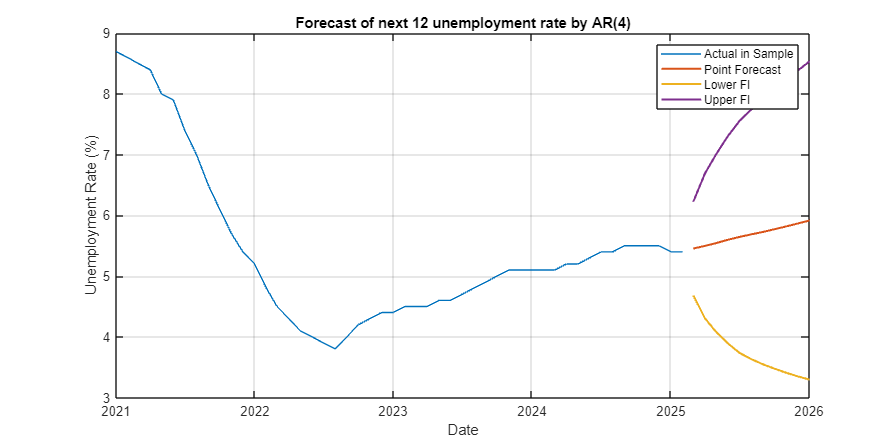

date_forecast = date_obj(end) + calmonths(1:12)';
data514 = data(data.observation_date >= datetime(2021,1,1), :);
figure('Position', [100, 100, 900, 450]);
plot(data514.observation_date,data514.CAUR);
hold on;
plot(date_forecast,ur_f,'LineWidth',1.5);
hold on;
plot(date_forecast,ur_fi,'LineWidth',1.5);
title('Forecast of next 12 unemployment rate by AR(4)');
legend('Actual in Sample', 'Point Forecast','Lower FI','Upper FI');
xlabel('Date'); ylabel('Unemployment Rate (%)');
grid on; datetick('x', 'yyyy', 'keepticks');